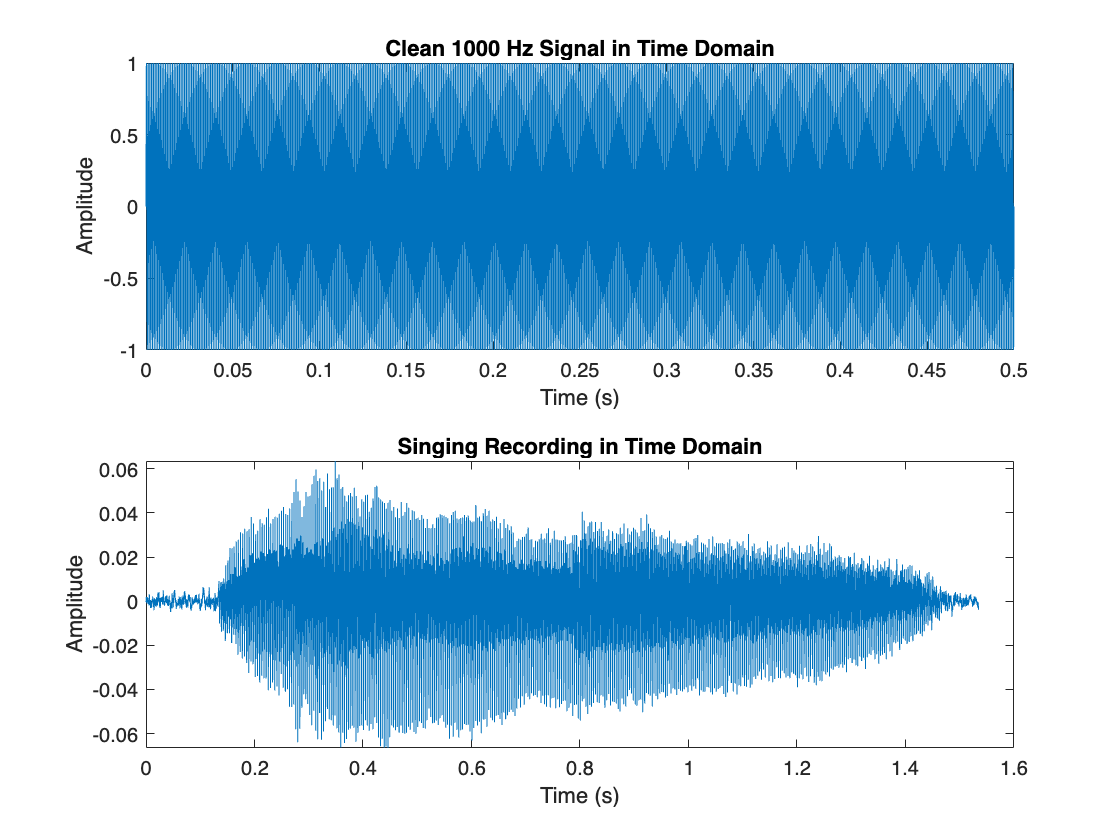

% Sampling frequency and time
fs = 48000;  % Sampling frequency
T = 0.5;       % Time window
t = 0:1/fs:T;  % Time vector for 1 second of audio

% Clean 1000 Hz signal
f = 1000;  % Frequency
clean_signal = sin(2*pi*f*t); 
sound(clean_signal, fs);  % For playing the signal

% Singing Recording
[recording, fs_recording] = audioread('Signals recording.m4a');
sound(recording, fs_recording);  % For playing singing recording

t_recording = linspace(0, length(recording)/fs, length(recording));  % Create new time vector based on recording length

% Plot Clean Signal in Time Domain
figure;
subplot(2,1,1);
plot(t, clean_signal);  % Plotting
xlabel('Time (s)');
ylabel('Amplitude');
title('Clean 1000 Hz Signal in Time Domain');

% Plot Singing Recording in Time Domain
subplot(2,1,2);
plot(t_recording, recording);  % Plotting
xlabel('Time (s)');
ylabel('Amplitude');
title('Singing Recording in Time Domain');

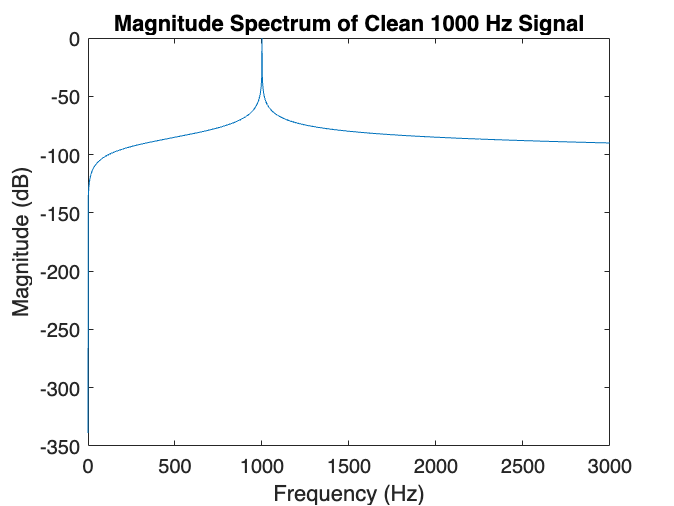


% FFT for Clean Signal
n_clean = length(clean_signal);  % Number of samples in clean signal
fft_clean = fft(clean_signal);  % FFT
f_clean = (0:n_clean-1)*(fs/n_clean);  % Frequency vector

% Compute magnitude and normalize by N (number of samples)
magnitude_clean = abs(fft_clean/n_clean);  
magnitude_clean(2:end-1) = 2*magnitude_clean(2:end-1);  % Multiply by 2 for positive frequencies
magnitude_clean_db = 20*log10(magnitude_clean);  % Convert magnitude to dB

% Step 8: FFT for Singing Recording
n_recording = length(recording);  % Number of samples in singing recording
fft_recording = fft(recording);  % Perform FFT on singing recording
f_recording = (0:n_recording-1)*(fs/n_recording);  % Frequency vector

% Compute magnitude and normalize by N (number of samples)
magnitude_recording = abs(fft_recording/n_recording);
magnitude_recording(2:end-1) = 2*magnitude_recording(2:end-1);  % Multiply by 2 for positive frequencies
magnitude_recording_db = 20*log10(magnitude_recording);  % Convert magnitude to dB

% Plot magnitude spectrum of clean signal
figure;
plot(f_clean, magnitude_clean_db);  % Plot magnitude in dB
xlim([0 3000]);  % Limit x-axis to 0-3000 Hz
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Magnitude Spectrum of Clean 1000 Hz Signal');

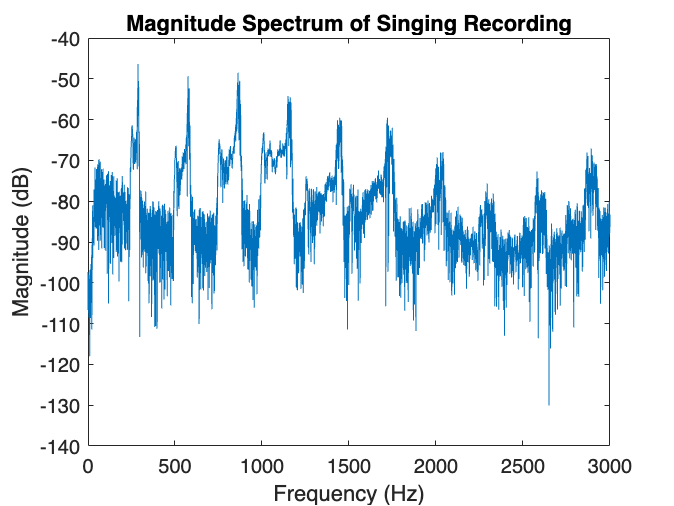


% Plot magnitude spectrum of singing recording
figure;
plot(f_recording, magnitude_recording_db);  % Plot magnitude in dB
xlim([0 3000]);  % Limit x-axis to 0-3000 Hz
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Magnitude Spectrum of Singing Recording');

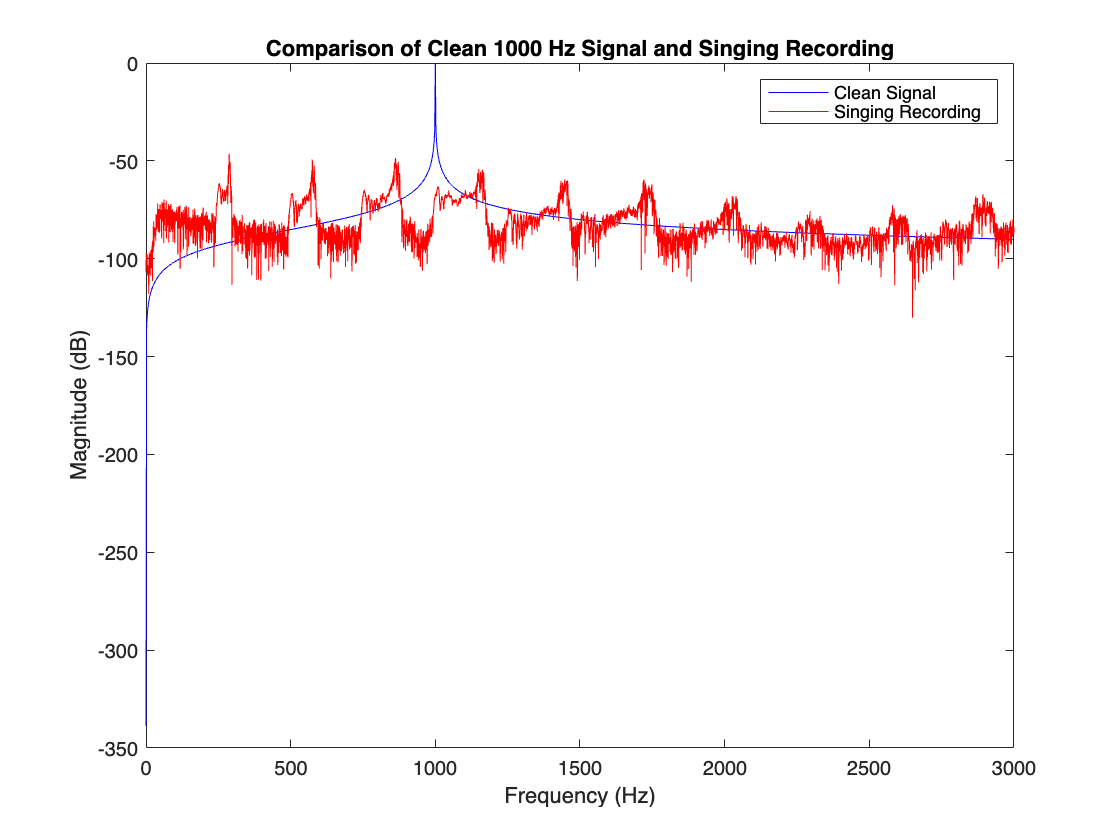


% Plot both on the same figure
figure;
plot(f_clean, magnitude_clean_db, 'b');  % Plot clean signal in blue
hold on;
plot(f_recording, magnitude_recording_db, 'r');  % Plot recorded voice in red
xlim([0 3000]);  % Limit x-axis to 0-3000 Hz
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Comparison of Clean 1000 Hz Signal and Singing Recording');
legend('Clean Signal', 'Singing Recording');
hold off;